# PRACTICA 1: REALIZAR UN MENU DE SELECCION DE ONDAS.

#### Objetivo: Realizar un menu donde el cliente pueda seleccionar la onda que desee ver con la Amplitud, frecuencia y Fase que desee.

Requisitos:

1.- el usuario puede seleccionar cualquiera de las siguientes ondas:

- Onda Senoidal.

- Onda Cuadrada.

- Onda Triangular.

2.- el usuario puede modificar los siguientes parametros:

- **(A) **Amplitud.

- **(F) **Frecuencia.

- ($\phi$) Fase.

3.-  el usuario visualizara la onda una vez puesto los parametros.

# Practica 1.1: HACER QUE LA ONDA SE ESCUCHE CON RELACION A LA TARJETA DE AUDIO.

#### Objetivo: Hacer que la onda ingresada se escuche con relacion a los Hercios maximos que alcanza el ser humano a percibir (20Khz) y considerando en cuanta frecuencia trabajan las tarjetas de sonido del ordenador (las frecuencias mas comunes).

## Comienzo del codigo

**1. Principio del programa:** para comenzar con el codigo, lo mas importante es realizar la limpieza general de las variables, pestañas y datos previamente cargados, de esta forma, no obtendremos errores 

una vez limpio todo lo necesario, podemos continuar con la definicion de otros conceptos.

**2. Definicion de funciones: **aqui definimos las funciones que necesitaremos para realizar el codigo, dividiendolo en tres sesiones:

- funcion que cree la interfaz y lea los parametros deseados por el usuario.

- funcion que pase los parametros a la funcion main o funcion de audio.

- funcion que cree el sonido de la onda y la grafica previsualizada.

- funcion que seleccione los hertz para que se escuche en tarjetas de sonido de un ordenador.

en la funcion de usuario donde creamos la interfaz de usuario, utilizamos funciones de UI, esta abre na ventana previa donde vemos todos los datos que vamos a llenar.

empezando por el tipo de onda, la amplitud, la frecuencia y la fase.

para la siguiente funcion de usuario, lo que hacemos es hacer que se grafique la onda pasandole los parametros previamente digitados, de esta manera, podemos visualizar la onda correctamente.

aqui podemos visualizar que vemos la onda de acuerdo a los parametros que dimos.

## POR LO TANTO, EL CODIGO FINAL QUEDARIA DE ESTA MANERA 

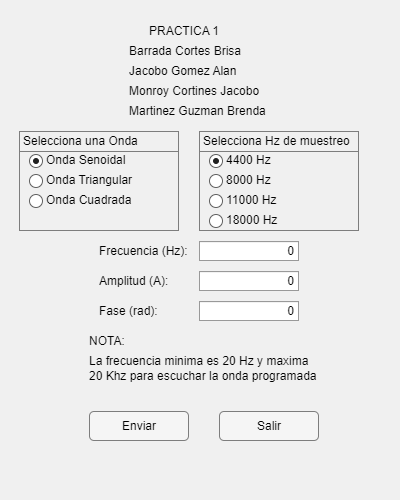

%Principio del programa para limpiar todo lo que tengo registro
clear
close all
clc

%funcion de usuario de el menu de ondas
    % Crear la ventana de la interfaz gráfica
    fig = uifigure('Name', 'PRACTICA 1: Configuración de Onda', 'Position', [500 300 400 500]);
    %name parametro que se llena con "configuracion de onda"
    %position parametro que se llena con [500 300 350 350] que inidca la
    %posicion del titulo
        
    %COLOCACION DE NOMBRES Y PRACTICA
    uilabel(fig,'Text', 'PRACTICA 1', 'Position', [150 460 150 20]);
    uilabel(fig,'Text', 'Barrada Cortes Brisa', 'Position', [130 440 150 20]);
    uilabel(fig,'Text', 'Jacobo Gomez Alan', 'Position', [130 420 150 20]);
    uilabel(fig,'Text', 'Monroy Cortines Jacobo', 'Position', [130 400 150 20]);
    uilabel(fig,'Text', 'Martinez Guzman Brenda', 'Position', [130 380 150 20]);

    % Grupo de selección de onda
    bg = uibuttongroup(fig, 'Position', [20 270 160 100], 'Title', 'Selecciona una Onda');
    %posicion donde se pondra title que es Selecciona una onda
    %el metodo uibuttongroup es un metodo que crea una categoria para ver
    %que parametro se selecciono en los radianbuttom
    uiradiobutton(bg, 'Text', 'Onda Senoidal', 'Position', [10 60 150 20]);
    uiradiobutton(bg, 'Text', 'Onda Triangular', 'Position', [10 40 150 20]);
    uiradiobutton(bg, 'Text', 'Onda Cuadrada', 'Position', [10 20 150 20]);
    %el metodo uiradiobutton es la generacion de un radianbuttom que se
    %puede seleccionar, crea en el UI este radiobuttom

    bg1 = uibuttongroup(fig, 'Position', [200 270 160 100], 'Title', 'Selecciona Hz de muestreo');
    %posicion donde se pondra title que es Selecciona una onda
    %el metodo uibuttongroup es un metodo que crea una categoria para ver
    %que parametro se selecciono en los radianbuttom
    uiradiobutton(bg1, 'Text', '4400 Hz', 'Position', [10 60 150 20]);
    uiradiobutton(bg1, 'Text', '8000 Hz', 'Position', [10 40 150 20]);
    uiradiobutton(bg1, 'Text', '11000 Hz', 'Position', [10 20 150 20]);
    uiradiobutton(bg1, 'Text', '18000 Hz', 'Position', [10 0 150 20]);

    % Campos de entrada para los parámetros
    %aqui entran los datos de la frecuencia, amplitud y fase que se guardan
    %en variables, el metodo uilabel solo es texto para que se visualice
    %que informacion entra, mientras que uieditfiel recibe el parametro y
    %lo guarda en las bariables input
    uilabel(fig, 'Text', 'Frecuencia (Hz):', 'Position', [100 240 100 20]);
    inputFrec = uieditfield(fig, 'numeric', 'Position', [200 240 100 20]);
    
    uilabel(fig, 'Text', 'Amplitud (A):', 'Position', [100 210 100 20]);
    inputAmp = uieditfield(fig, 'numeric', 'Position', [200 210 100 20]);

    uilabel(fig, 'Text', 'Fase (rad):', 'Position', [100 180 100 20]);
    inputFase = uieditfield(fig, 'numeric', 'Position', [200 180 100 20]);

    uilabel(fig,'Text', 'NOTA:', 'Position', [90 150 150 20]);
    uilabel(fig,'Text', 'La frecuencia minima es 20 Hz y maxima', 'Position', [90 130 250 20]);
    uilabel(fig,'Text', '20 Khz para escuchar la onda programada', 'Position', [90 115 250 20]);

    % Botón de Enviar
    %este es el boton donde manda los parametros y la onda seleccionada
    %para que envie la configuracion de la grafica y se pueda visualizar
    btnEnviar = uibutton(fig, 'Text', 'Enviar', 'Position', [90 60 100 30], ...
                         'ButtonPushedFcn', @(btn, event) graficarOnda(bg, bg1, inputFrec, inputAmp, inputFase));

    % Botón de Salir
    %este botton es para salir del programa
    btnSalir = uibutton(fig, 'Text', 'Salir', 'Position', [220 60 100 30], ...
                        'ButtonPushedFcn', @(btn, event) close(fig));


%funcion de usuario para graficar la onda
function graficarOnda(bg, bg1, inputFrec, inputAmp, inputFase)
    % Obtener la opción seleccionada
    seleccion = bg.SelectedObject.Text;
    seleccion1 = bg1.SelectedObject.Text;

    switch seleccion1
        case "4400 Hz", fs = 4400;
        case "8000 Hz", fs = 8000;
        case "11000 Hz", fs = 11000;
        case "18000 Hz", fs = 18000;
        otherwise, fs = 8000;
    end 

    % Obtener valores ingresados por el usuario
    f = inputFrec.Value;
    A = inputAmp.Value;
    fase = inputFase.Value;

    %condicionales por si el usuario ingresa valores nulos, asi si el
    %usuario deja algun parametro en 0, inicializa con valores standar, es
    %decir en fase y amplitud de 1, mientras que la fase inicia en 0 por
    %default
    if isnan(f) || f < 20 || f > 20000, f = 20; end  % Frecuencia por defecto = 20 Hz
    if isnan(A) || A == 0, A = 1; end  % Amplitud por defecto = 1
    if isnan(fase), fase = 0; end      % Fase por defecto = 0 rad

    % Definir el tiempo (5 segundos para mostrar ciclos completos)
    t = linspace(0, 5, fs);

    % Graficar solo un período para mejor visualización
    T = 1/f; % Calculamos el período de la onda
    tp = linspace(0, T, 1000); % Definimos un solo ciclo con puntos suficientes

    % Generar la señal según la opción seleccionada
    %usando un switch para seleccionar el caso que se espera para generar
    %la onda esperada
    switch seleccion
        %defincion de la onda senoidal (funcion que la define)
        case 'Onda Senoidal'
            y = A * sin(2 * pi * f * t + fase);
            y_periodo = A * sin(2 * pi * f * tp + fase);
            titulo = 'Onda Senoidal';

        case 'Onda Triangular'
        %defincion de la onda Triangular (funcion que la define)
            T = 1 / f; % Período de la onda
            y = 2 * A * abs(2 * mod(t + fase / (2 * pi), T) / T - 1) - A;
            y_periodo = 2 * A * abs(2 * mod(tp + fase / (2 * pi), T) / T - 1) - A;
            titulo = 'Onda Triangular';

        case 'Onda Cuadrada'
            %defincion de la onda cuadrada (funcion que la define)
            y = A * sign(sin(2 * pi * f * t + fase));
            y_periodo = A * sign(sin(2 * pi * f * tp + fase));
            titulo = 'Onda Cuadrada';

        otherwise
            return;
    end

    % Graficar la señal real
    figure;
    plot(t, y, 'LineWidth', 2);
    grid on;
    xlabel('Tiempo (s)');
    ylabel('Amplitud');
    title(titulo);
    ylim([-A-0.2, A+0.2]);
    % Sonido
    sound (y,fs);

   %grafica que muestra solo un periodo
    figure;
    plot(tp, y_periodo, 'LineWidth', 2);
    grid on;
    xlabel('Tiempo (s)');
    ylabel('Amplitud');
    title([titulo, ' (Un Período)']);
    ylim([-A-0.2, A+0.2]);
end
